# APMA 2501 - Programming in R & MATLAB: MATLAB Unit 5

## **Apply Matrix Calculation**

- Topic 1: A Common Use of Matrices

- Topic 2: Numerical Differentiation

What we will do today:

- Use matrices to store and organize function values on any x-y grid

- Create contour plots to visualize a field over a 2D region

- Apply matrix methods to solve temperature distribution problems

## MATLAB Copilot Topic #4: Autocompletion

MATLAB Copilot allows users to generate code suggestions based on the code context they have already written, helping them complete functions, expressions, and common programming patterns more efficiently. This autocompletion feature can speed up coding, reduce repetitive typing, and help users recall correct syntax or useful built-in functions. 

Key tips and advice for using autocompletion:

- Review suggestions before accepting them. Autocompletion can save time, but you should still check that the suggested code matches your goal, as deviations can still exist inside.

- If the suggested code does not look good, you probably need to work through the problem yourselves to avoid those mistakes. Autocompletion provides suggestions, not guaranteed correct answers.

## Topic 1: A Common Use of Matrices

Visualize a function of the form: $z=f\left(x,y\right)$

Think of z as an elevation that depends on the coordinates x andy of the location. We can make a contour plot for z:

- Set up x-y grid

- Evaluate function at all grid points

- Draw the contours

### Warm-up example of contour plots on [MATLAB logo function](https://www.mathworks.com/company/technical-articles/the-mathworks-logo-is-an-eigenfunction-of-the-wave-equation.html)

Z = membrane(1, 100); % first eigenfunction of the L-shaped membrane
n = size(Z,1);
x = linspace(-1,1,n);
y = linspace(-1,1,n);

figure

subplot(1,2,1)
surf(x, y, Z)
shading interp
axis tight
title('3D Surface')
xlabel('x')
ylabel('y')
zlabel('z')

subplot(1,2,2)
contour(x, y, Z, 20)
axis equal tight
title('Contour Plot')
xlabel('x')
ylabel('y')
colorbar

#### Setting up the grid

x = linspace(0,6,13);
y = linspace(0,4,9);

% fVals is matrix of functionvalues at all grid points 
fVals = zeros(9,13);

#### Evaluating the Field

Suppose we have a temperature distribution function: $T_{\text{plate}}(x,y)=100e^{-0.4\left((x-1)^2+0.7(y-3)^2\right)}+80e^{-0.2\left(2(x-5)^2+1.5(y-1)^2\right)}$, over a rectangular area with x in [0, 6] and y in [0, 4].

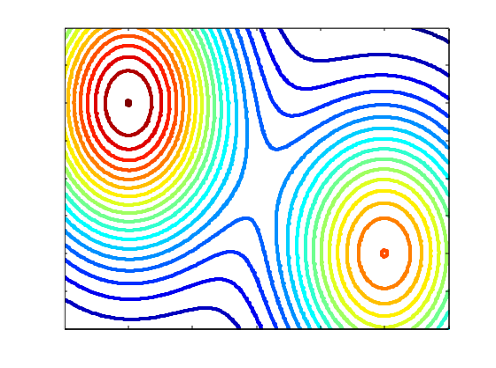                                  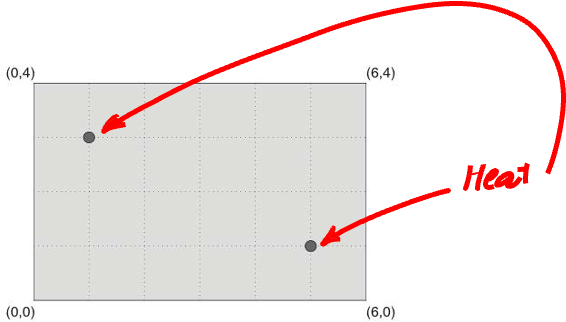

***Figure:**** (left) the smooth contour plot for T_plate; (right) the rectangular x-y domain area with two random locations indicated*

We can code this function in MATLAB as below:

function t = T_plate(x,y)
% t is temperature at (x,y)
    t = 100*exp(-.4*((x-1)^2 + 0.7*(y-3)^2))+...
    80*exp(-.2*(2*(x-5)^2 + 1.5*(y-1)^2));
end

#### Making a Contour Plot

Now let's evaluate the function values at all grid points:

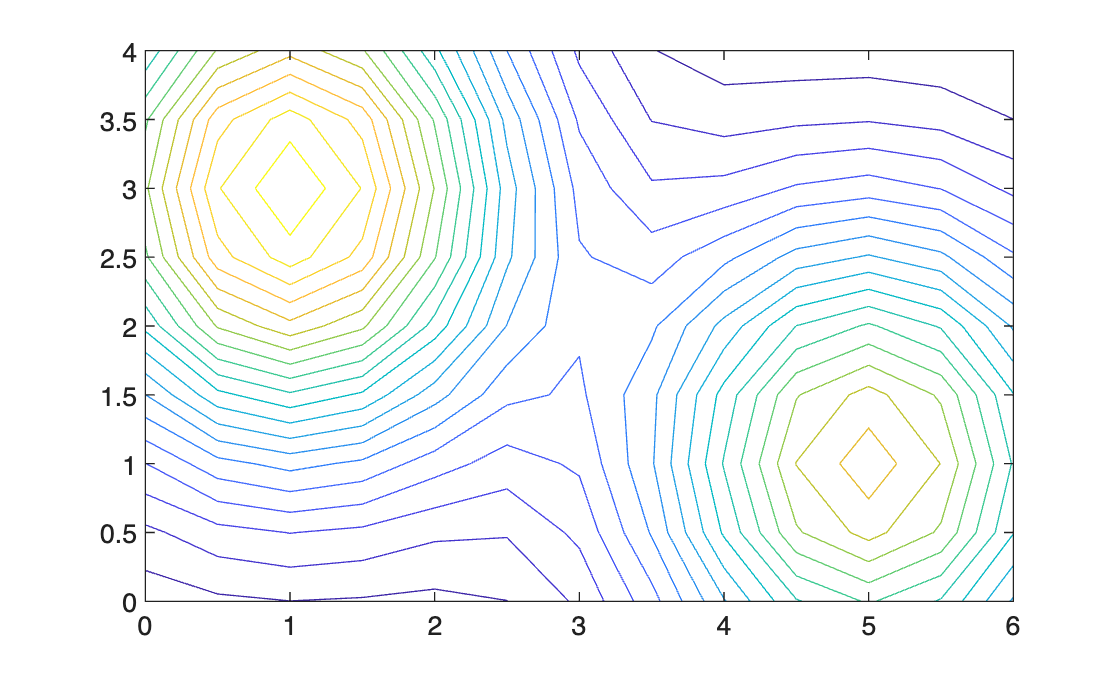

% Setting up a matrix of function evalutions
for j=1:13

    for i=1:9

    end
end

and make the contour plot based on them

contour(x, y, fVals, 20)

Note: 20 in the last argument means that we are using 20 contours in total.

### Summary

- Matrices are frequentlyused tostore a **field of** **data** in x-y space.

- We can visualize this field witha **contour ****plot**.

## Topic 2: Numerical Differentiation ---> see the lecture slides

### Example problem in the lecture slides #19-28

We have a bar with a fixed temperature at each end, and discrtized into four sections by 5 points (including the ends), and then solve for the overall temperature distribution in this material.

% Coefficient matrix
A = [ 1   0   0   0   0;
      1  -2   1   0   0;
      0   1  -2   1   0;
      0   0   1  -2   1;
      0   0   0   0   1 ];

% Right-hand side vector

Solution vector T =


b = [100; 0; 0; 0; 50];

  100.0000
   87.5000
   75.0000
   62.5000
   50.0000




% Solve for the T vector
T = A \ b;

% Display result
disp('Solution vector T =')
disp(T)